# image preprocessing

## 1. adjusting contrast

### 1.3 Histogram Matching

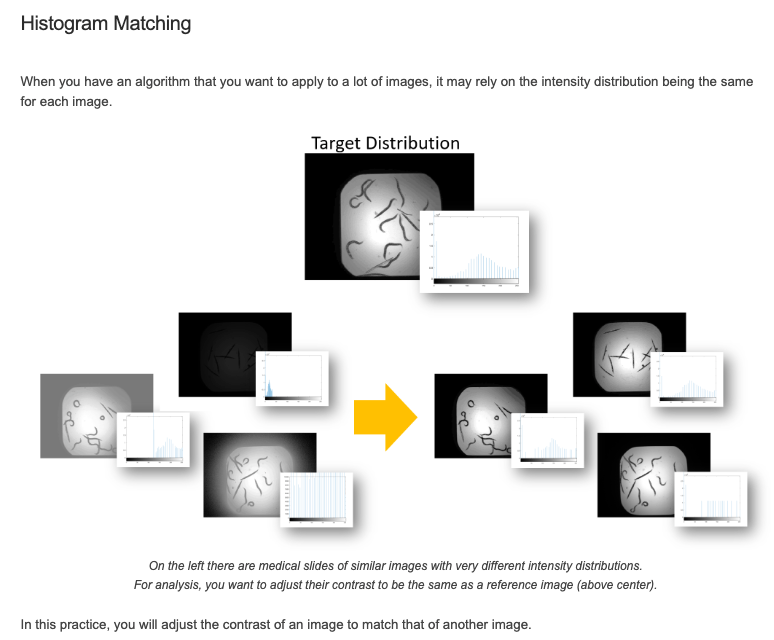

來看一下，原始的兩張圖：

%roundworms = imread("mlp_course_files/worms.jpg");
%roundworms2 = imread("mlp_course_files/worms2.jpg");
%imshowpair(roundworms, roundworms2, "montage")

### 1.4 unevenly lit background

這個的意思是，背景的亮源是不均勻的，如下圖

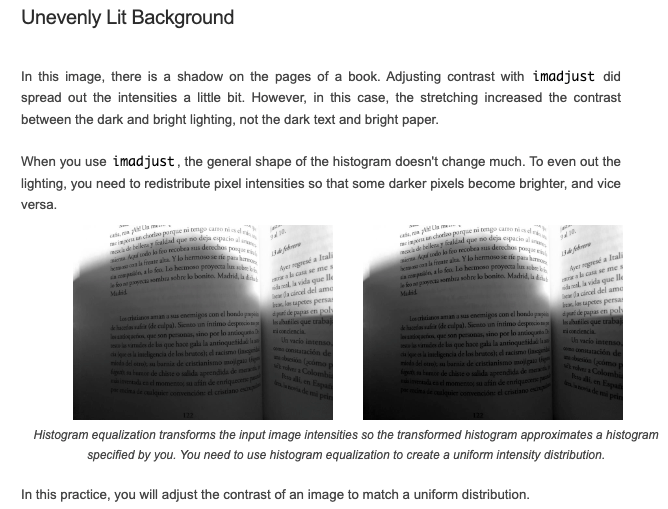

來看一下原圖：

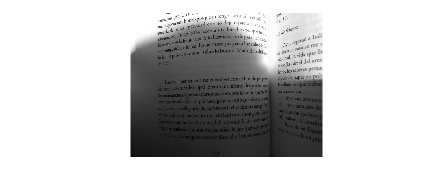

book = imread("mlip_course_files/book.jpg");
book = im2gray(book);
imshow(book)

如果只用之前學過的 `imadjust()` 來調整，是不夠的：

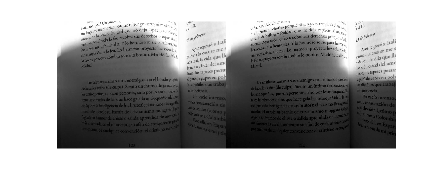

imshowpair(book,imadjust(book),"montage")

因為 `imadjust` 沒改變 histogram:

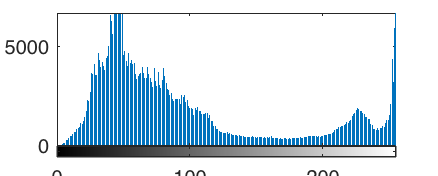

imhist(book)

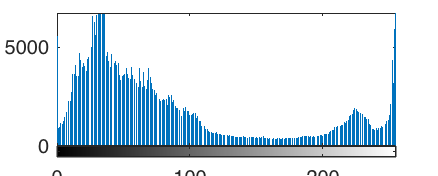

imhist(imadjust(book))

那這邊要學的，是 histogram equalization，想辦法把 intensity 變成 uniform distribution

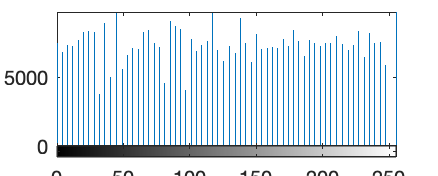

bookEq = histeq(book);
imhist(bookEq)

那就可以把原圖變成：

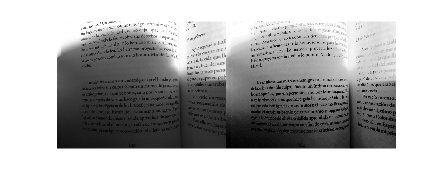

imshowpair(book, bookEq, "montage")

確實有好一點了。

然後還有一招，是做 local 版的 histogram equalization

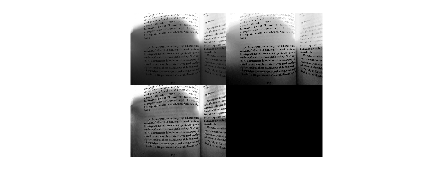

bookAdapt = adapthisteq(book);
montage({book, bookEq, bookAdapt})

### 1.5 block processing